# Angle between the main-lobe of earth station antenna and terrestrial user

clc
clear all
sympref('FloatingPointOutput', false);

### Hourani

$\theta$: orientation of the main-lobe of earth station antenna

syms theta phi r_e  h N
phi = acot((1 + r_e/h)*tan(theta))

$$phi = \mathrm{acot}\left(\tan\left(\theta \right)\,\left(\frac{r_{e}}{h}+1\right)\right)$$

pdf of $\theta$

f_theta(theta, N, r_e, h) = (N/2)*sin(phi)*...
    exp(-(N/2)*(1- cos(phi)))*(1+ r_e/h)*sec(theta)^2*...
    1/(1 + (1 + r_e/h)^2*tan(theta)^2)

$$f\_theta(theta, N, r\_e, h) = \frac{N\,{\mathrm{e}}^{\frac{N\,\left(\frac{1}{\sqrt{\frac{1}{{\tan\left(\theta \right)}^{2}\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}+1}}-1\right)}{2}}}{2\,{\cos\left(\theta \right)}^{2}\,\tan\left(\theta \right)\,\sqrt{\frac{1}{{\tan\left(\theta \right)}^{2}\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}+1}\,\left({\tan\left(\theta \right)}^{2}\,{\left(\frac{r_{e}}{h}+1\right)}^{2}+1\right)}$$

f_1_theta = @(theta) f_theta( theta, 1000, 6371e3, 500e3)

f_1_theta = function_handle with value:
    @(theta)f_theta(theta,1000,6371e3,500e3)



x_theta = linspace(0.1, pi/2);
m = length(x_theta)

m = 100

f_theta_val = zeros(1,m);
for j = [1:m]
    f_theta_val(j) = f_1_theta(x_theta(j));
end

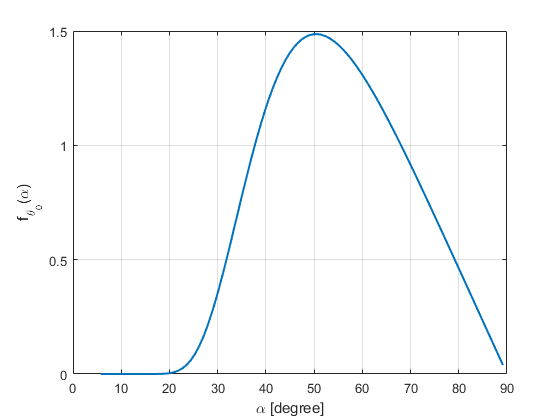

figure
plot(rad2deg(x_theta), f_theta_val, 'LineWidth', 1.5)
xlabel('\alpha [degree]')
ylabel('f_{\theta_0}(\alpha)')
grid on;

syms beta % direction of the terrestrial user vector
syms alpha % angle between earth station main-lobe and user

% alpha = acos(cos(beta)*cos(theta))

**Steps:**

- Find pdf of X = cos(theta)               [DONE]

- Find pdf of Y = cos(beta)                [DONE]

- Find pdf of Z = cos(alpha) = XY      [DONE]

- Find pdf of alpha = acos(Z)

syms X Y Z

f_X(X) = (1/sqrt(1-X^2))*f_theta(acos(X))

$$f\_X(X) = \begin{array}{l} \frac{N\,{\mathrm{e}}^{\frac{N\,\left(\frac{1}{\sigma_{1}}-1\right)}{2}}}{2\,X\,\left(X^{2}-1\right)\,\sigma_{1}\,\left(\frac{\left(X^{2}-1\right)\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}{X^{2}}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1-\frac{X^{2}}{\left(X^{2}-1\right)\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}} \end{array}$$

f_Y(Y) = piecewise(...
    Y<-1, 0, ...
    -1 < Y < 1, 1/(2*pi*sqrt(1-Y^2)) ,...
    Y>1, 0)

$$f\_Y(Y) = \left\{ \begin{array}{cl} 0 & \text{ if }Y<-1\\ \frac{1}{2\,\pi \,\sqrt{1-Y^{2}}} & \text{ if }Y\in \left(-1,1\right)\\ 0 & \text{ if }1<Y \end{array}\right.$$

f_Z(Z) = int(f_X(X)/(pi*sqrt(X^2 - Z^2)), X, abs(Z), 1)

$$f\_Z(Z) = \begin{array}{l} \int_{\left|Z\right|}^{1}\frac{N\,{\mathrm{e}}^{\frac{N\,\left(\frac{1}{\sigma_{1}}-1\right)}{2}}}{2\,X\,\pi \,\left(X^{2}-1\right)\,\sqrt{X^{2}-Z^{2}}\,\sigma_{1}\,\left(\frac{\left(X^{2}-1\right)\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}{X^{2}}-1\right)}\mathrm{d}X\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1-\frac{X^{2}}{\left(X^{2}-1\right)\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}} \end{array}$$

f_alpha(alpha, N, r_e, h) = f_Z(cos(alpha))*abs(sin(alpha)) 

$$f\_alpha(alpha, N, r\_e, h) = \begin{array}{l} \left|\sin\left(\alpha \right)\right|\,\int_{\left|\cos\left(\alpha \right)\right|}^{1}\frac{N\,{\mathrm{e}}^{\frac{N\,\left(\frac{1}{\sigma_{1}}-1\right)}{2}}}{2\,X\,\pi \,\left(X^{2}-1\right)\,\sigma_{1}\,\sqrt{X^{2}-{\cos\left(\alpha \right)}^{2}}\,\left(\frac{\left(X^{2}-1\right)\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}{X^{2}}-1\right)}\mathrm{d}X\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1-\frac{X^{2}}{\left(X^{2}-1\right)\,{\left(\frac{r_{e}}{h}+1\right)}^{2}}} \end{array}$$

f_ALPHA = matlabFunction(f_alpha)

f_ALPHA = function_handle with value:
    @(alpha,N,r_e,h)abs(sin(alpha)).*integral(@(X)(N.*exp((N.*(1.0./sqrt(-(X.^2.*1.0./(r_e./h+1.0).^2)./(X.^2-1.0)+1.0)-1.0))./2.0).*1.0./sqrt(-(X.^2.*1.0./(r_e./h+1.0).^2)./(X.^2-1.0)+1.0).*1.0./sqrt(-cos(alpha).^2+X.^2))./(X.*pi.*(X.^2-1.0).*(1.0./X.^2.*(X.^2-1.0).*(r_e./h+1.0).^2-1.0).*2.0),abs(cos(alpha)),1.0)


f_1 = @(alpha) f_ALPHA( alpha, 1000, 6371e3, 500e3)

f_1 = function_handle with value:
    @(alpha)f_ALPHA(alpha,1000,6371e3,500e3)


x_alpha = linspace(0, pi);
m = length(x_alpha)

m = 100

f_alpha_val = zeros(1,m);
for j = [1:m]
    f_alpha_val(j) = f_1(x_alpha(j));
end

$\alpha$: angle between the main-lobe of earth station antenna and terrestrial user

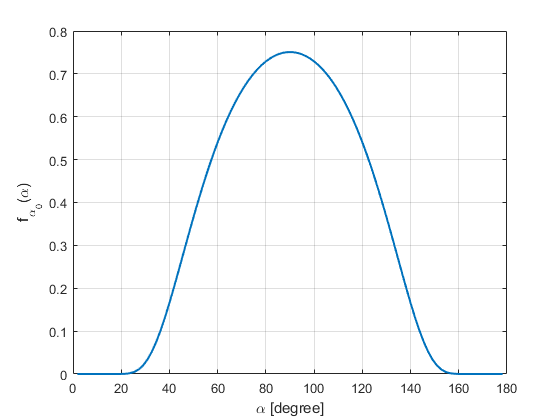

figure
plot(rad2deg(x_alpha), f_alpha_val, 'LineWidth', 1.5)
xlabel('\alpha [degree]')
ylabel('f_{\alpha_0}(\alpha)')
grid on;

epsilon = 1e-3;
f_int_full = integral(@(alpha) f_1(alpha), epsilon,  pi-epsilon,'ArrayValued',true)

f_int_full = 1.0000